clear all; clc
rng(123)
%%{
t = linspace(1,50,200);
V{1} = [sin(2*pi*t/50)', sin(2*pi*t/25)'];
V{2} = V{1}(1:2:end,:);
V{3} = V{1}(1:3:end,:);
T = cpdgen(V);
T=T+0.1*rand(size(T));
%}
% T=reshape(1:2400, 10, 12, 20);
[Tm,~,~] =  give_miss_3(T, 0.54);
Wo=~isnan(squeeze(Tm(:,:,1)));
% figure(1); surf3(Tm);

% [Cores] = tt_fs(Tm, Wo, [1 3 3 1]); 
% Xrec = TT_Full(Cores);
% surf3(Xrec);
% Trec = TT_Full(Cores);
% figure(2); surf3(Trec);

%{
clc;
X=Tm+0.1*rand(size(Tm)); 
W=Wo; 
ranks=[1 2 2 1];
%Input tensor with missing in last mode
%ranks = [1, r1, r2, r3, 1]
d=ndims(X);
sze = size(X);
Cores3 = cell(1,d);

% Last Core
[Cores3{d}, Xmr] = CoreN(X, W, ranks(3));
sze = size(Xmr);
% First Core
n=1; 
notn = [1:n-1 n+1:d-1]
Xn = permute(Xmr, [notn n d]);
Xn = reshape(Xn, [prod(sze(notn)) sze(n) sze(d)]);
Wn = permute(W, [notn n]);
Wn = reshape(Wn, [prod(sze(notn)) sze(n)]);
[Cores3{n}] = grid_complete(Xn, Wn, ranks(n+1));
%%{
G20 = tmprod(rep0(Xmr), squeeze(Cores3{1}).', 1);
Xmrg = tmprod(rep0(Xn), Cores3{n}.', 2);
Xmrg(Xmrg==0)=NaN;
Xmrg = permute(Xmrg, [2, 1, 3]);
Xmrg = reshape(Xmrg, [ranks(2), sze(notn), ranks(d)]);
%}

% Updated core
% Xredt = permute(cat(3, Xred{:}), [1,3,2]);

% GL_m = squeeze(Cores{1});
% GR_m = squeeze(Cores{3});
% k=2;
% Xk = GL_m*squeeze(Cores{2}(:,k,:))*GR_m;
% Xraw_k=squeeze(Tm(:,k,:));

% % On assuming orthonormalility of coloums of GL, GR
% G2 = zeros(ranks(2), sze(2), ranks(3));
% for i =1:sze(2)
%     G2(:,i,:) = GL_m.'*rep0(squeeze(X(:,i,:)))*GR_m.' ;
% end

NOW TRYING TO MAKE IT WORK ON REHSPAED HIGHER OREDR TENSORS

clc;
Trsh = reshape(Tm, 10,20,10,10,67);
szeT = size(Trsh);
dT=ndims(Trsh); 
CoresT=cell(1,dT);
WT=~isnan(squeeze(Trsh(:,:,:,:,1))); 
ranksT=[1 3 3 4 5 1];
%% Last Core
[CoresT{dT}, Tmr] = CoreN(Trsh, WT, ranksT(dT));
szeT = size(Tmr)

szeT =     10    20    10    10     5


%% First cores
n=1; 
notn = [n+1:dT-1]

notn =      2     3     4


Tn = permute(Tmr, [notn n dT]);
Tn = reshape(Tn, [prod(szeT(notn)) szeT(n) szeT(dT)]);
Wn = permute(WT, [notn n]);
Wn = reshape(Wn, [prod(szeT(notn)) szeT(n)]);
[CoresT{n}] = grid_complete(Tn, Wn, ranksT(n+1));
CoresT{n} = reshape(CoresT{n}, [1, size(CoresT{n})])

CoresT = 1×5 cell array
    {1×10×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {5×67 double}


szeT=size(Tmr);

Tmrg= tmprod(rep0(Tmr), squeeze(CoresT{1}).', 1);
size(Tmrg)

ans =      3    20    10    10     5


Tmrg(Tmrg==0)=NaN;

Tmr2 = reshape(Tmrg, ranksT(2)*szeT(2), szeT(3),[],  szeT(dT));
size(Tmr2)

ans =     60    10    10     5


W=~isnan(squeeze(Tmr2(:,:,:,1)));

[UU,su] = mlsvd_fs(Tmr2, W, [3,3,4,5]);
CoresT{2}=reshape(UU{1}, 3, 20,3)

CoresT = 1×5 cell array
    {1×10×3 double}    {3×20×3 double}    {0×0 double}    {0×0 double}    {5×67 double}


% 3rd core
Tmrg = tmprod(rep0(Tmr2),squeeze(UU{1}).', 1);
Tmrg(Tmrg==0)=NaN;
size(Tmrg)

ans =      3    10    10     5


Tmr3 = reshape(Tmrg, ranksT(3)*szeT(3), szeT(4),  szeT(dT));
size(Tmr3)

ans =     30    10     5


W=~isnan(squeeze(Tmr3(:,:,1)));

[UU,su] = mlsvd_fs(Tmr3, W, [4,4,5]);
CoresT{3}=reshape(UU{1}, 3, 10, 4)

CoresT = 1×5 cell array
    {1×10×3 double}    {3×20×3 double}    {3×10×4 double}    {0×0 double}    {5×67 double}


% 4th core
Tmrg = tmprod(rep0(Tmr3),squeeze(UU{1}).', 1);
Tmrg(Tmrg==0)=NaN;
size(Tmrg)

ans =      4    10     5


Tmr4=Tmrg;

CoresT{4}=Tmr4;
% [G_nl,G_nr]=G_nmode_devide(CoresT,4);
% GL_m = reshape(G_nl, [], ranksT(4));
% GR_m = reshape(G_nr, ranksT(4+1), []);
% FME = kron(GR_m', eye(szeT(4))); %I_n: size(sze(n)); Frame matrix 
% FME = kron(FME, GL_m);
% v_T = TT_unfold(Tmr, size(Tmr), dT);

size(FME), size(v_T)

ans =      1340000         200


ans =       100000           1


%[core_mid_opt,~, ~,~] = solve_LS_miss(FME, v_T);
numel(Tmr)

ans = 100000

Trex = TT_Full(CoresT);

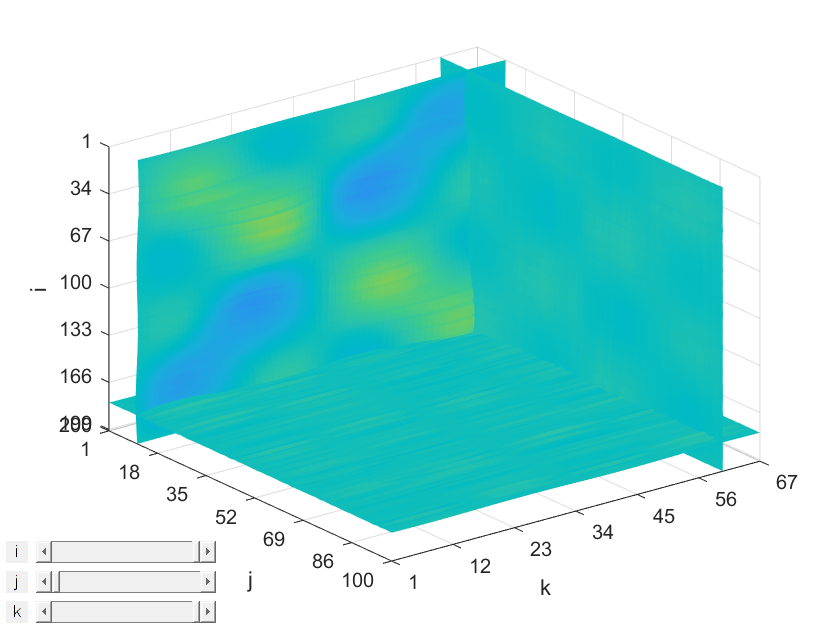

Trex = reshape(Trex, 200, 100, 67);
surf3(Trex)

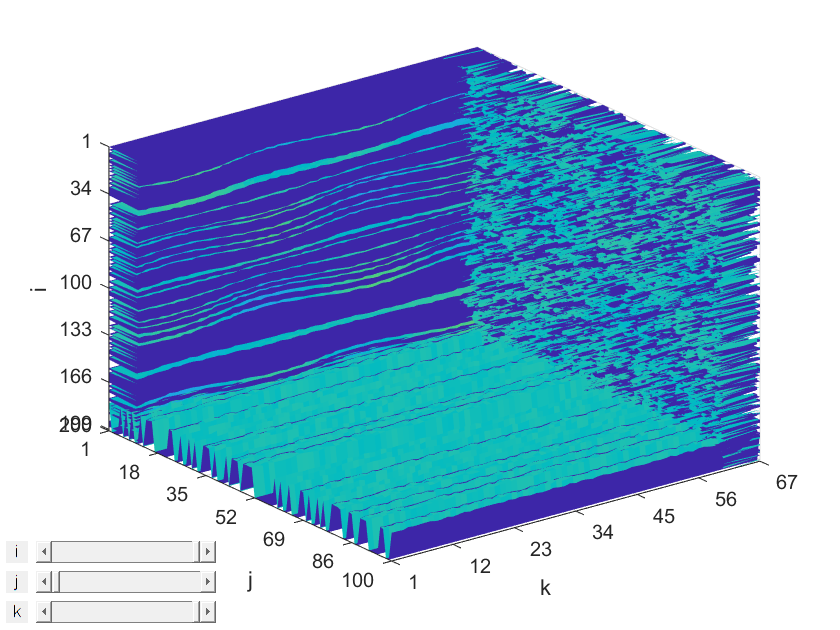

figure(222)
surf3(Tm)

clc
% Function Based
T = reshape(Tm, 10,20,10,10,67);
szeT = size(T);
dT=ndims(T); 
Cores=cell(1,dT);
idx = repmat({':'}, 1, dT - 1);
W = ~isnan(squeeze(T(idx{:},1)));
ranksT = [1,3,3,3,3,1];
%% Last Core
[Cores{dT}, Tr_n] = CoreN(T, W, ranksT(dT));

%init 
Wn=W;
sze_n=size(Tr_n);
d_n = dT;
for n=1:dT-2
    notn = 2:d_n-1;
    Tn = permute(Tr_n, [notn 1 d_n]);
    Tn = reshape(Tn, [prod(sze_n(notn)) sze_n(1) sze_n(d_n)]);
    Wn = permute(Wn, [notn 1]);
    Wn = reshape(Wn, [prod(sze_n(notn)) sze_n(1)]);
    [cr] = grid_complete(Tn, Wn, ranksT(n+1));
    Cores{n} = reshape(cr,ranksT(n), szeT(n), ranksT(n+1));
    % compress in n-th mode
    Tr_n = tmprod(rep0(Tr_n),cr.', 1);
    Tr_n(Tr_n==0)=NaN;
    sze_n=size(Tr_n)
    s12 = prod(sze_n(1:2));
    sze_n(1:2)=[];
    sze_n = [s12 sze_n];
    Tr_n = reshape(Tr_n, sze_n);
    % update
    d_n = ndims(Tr_n);
    idx = repmat({':'}, 1, d_n - 1);
    Wn = ~isnan(squeeze(Tr_n(idx{:},1)));
end

sze_n =      3    20    10    10     3


sze_n =      3    10    10     3


sze_n =      3    10     3


Tr_n(isnan(Tr_n))=0;
Cores{dT-1} = reshape(Tr_n,ranksT(n), szeT(n), ranksT(n+1))

Cores = 1×5 cell array
    {1×10×3 double}    {3×20×3 double}    {3×10×3 double}    {3×10×3 double}    {3×67 double}
